Generate three sinusoidal signals x1(k), x2(k) and x3(k) with a fundamental frequency of 50, 100Hz and 150Hz, respectively, amplitude A = 1, sampling frequency equal to 1kHz and duration equal to 1 s.

Generate x4(k)=x1(k)+x2(k)+x3(k). 	

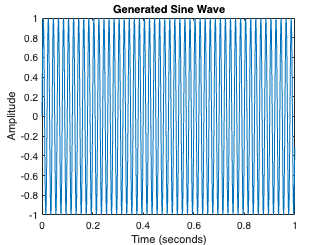

f1 = 50; %Hz
f2 =  100; %Hz
f3 =  150; %Hz
A = 1; % amplitude
f_s = 1000;
t = [0:1/1000:1];
d = 1 - 0; % duration


% function [x]=generate_sine(frequency,A,fs,duration)
x1 = generate_sine(f1, A, f_s, d);

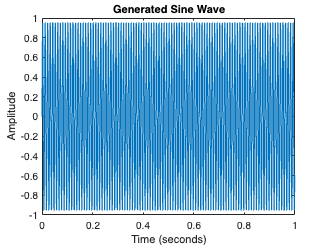

x2 = generate_sine(f2, A, f_s, d);

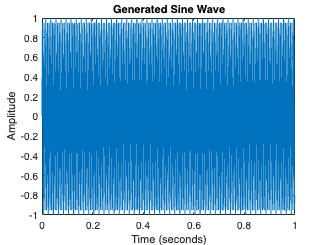

x3 = generate_sine(f3, A, f_s, d);


x4 = x1 + x2 + x3;


# **Yule-Walker **

The Yule-Walker method estimates the autoregressive (AR) model parameters based on the autocorrelation sequence of the signal.

Matlab has a precompiled function implementing the Yule-Walker method. Its name is *aryule.m*. Check the help of the function to understand the outputs. 

**Apply the function on the signal x4(k) and identify the optimal model order**. 

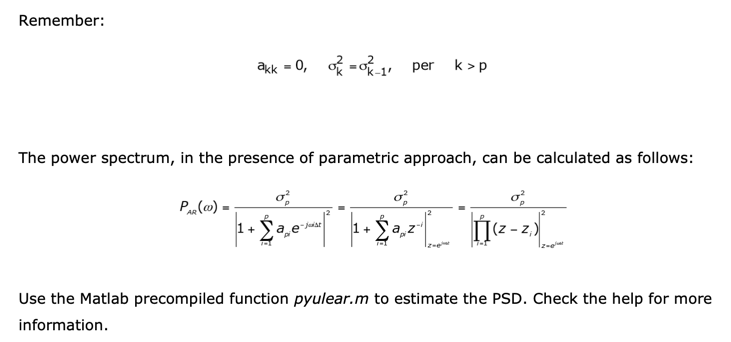

**Try to analyze the effect of the order on the PSD estimation. **



% Parameters for Yule-Walker
threshold_yw = 0.00001; % Variation threshold of eyw
max_order_yw = 100; % Max order to consider
eyw_values = zeros(1, max_order_yw); % Store variance values

% Initialization of previous eyw to compare
[~, prev_eyw] = aryule(x4, 1); % Only eyw is needed from the first order

% Yule-Walker method to find optimal order
for order_yw = 2:max_order_yw
    % Calculate the coefficient and the variance of AR
    [~, eyw] = aryule(x4, order_yw);
    
    eyw_values(order_yw) = eyw; % Store error variance for current order

    % Monitor the variance of eyw
    if abs(prev_eyw - eyw) < threshold_yw
        fprintf('The optimal order is %d with eyw = %.6f\n', order_yw, eyw);
        break;
    end

    % Update the previous eyw
    prev_eyw = eyw;
    
    % If it gets up to the max order without satisfying the conditions
    if order_yw == max_order_yw
        fprintf('Reached the maximum order (%d) with eyw = %.6f\n', max_order_yw, eyw);
    end
end

The optimal order is 20 with eyw = 0.007160


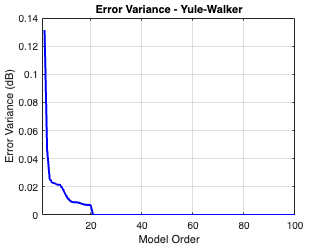


% Plotting error variance for Yule-Walker
figure;
plot(2:max_order_yw, eyw_values(2:end), 'b-', 'LineWidth', 2); % eyw_values for orders 2 to max
title('Error Variance - Yule-Walker');
xlabel('Model Order');
ylabel('Error Variance (dB)');
xlim([1 max_order_yw]);
grid on;

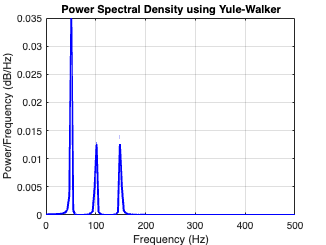


% PSD estimation using optimal Yule-Walker order
optimal_order_yw = find(eyw_values == min(eyw_values), 1, 'last'); % Ensure it captures the last minimal variance
[pxx_yw, f] = pyulear(x4, optimal_order_yw, [], f_s);


% Plot the Power Spectral Density
figure;
plot(f, pxx_yw, 'b', 'LineWidth', 2);
title('Power Spectral Density using Yule-Walker');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

**Error Variance Plot**:

- The error variance decreases rapidly and stabilizes at a very low value.

- This stabilization occurs around a model order of approximately 10 to 20.

- Indicates that increasing the model order beyond this point does not significantly reduce the error variance.

- Suggests that the Yule-Walker method captures the essential signal characteristics effectively at a relatively low order.

**Power Spectral Density (PSD) Plot**:

- The PSD shows distinct peaks at around 50 Hz, 100 Hz, and 150 Hz.

- These peaks correspond to the fundamental frequencies of the sinusoidal components in the signal.

- The sharp and high peaks indicate dominant frequency components at these frequencies.

- The presence of multiple peaks in the PSD confirms that the Yule-Walker method successfully resolves the significant spectral components of the combined signal.

**Conclusion**:

- The Yule-Walker method effectively identifies the optimal model order as shown by the error variance plot.

- The PSD plot, with distinct peaks at 50 Hz, 100 Hz, and 150 Hz, demonstrates the method's capability to capture the significant spectral components accurately.

- The clear resolution of multiple frequency components in the PSD suggests that the Yule-Walker method is effective for this signal, accurately reflecting its fundamental frequencies.